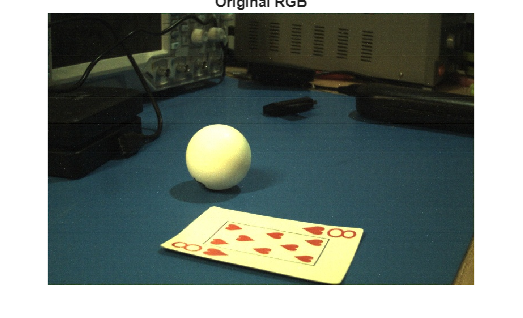

clear; close all; clc;

% ---- Load image ----
img = imread("images/right7.jpg");

figure(1);
imshow(img);
title('Original RGB');

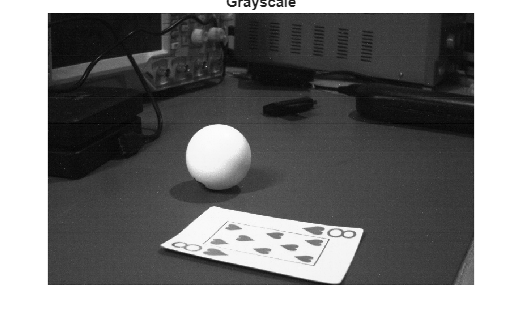


% ---- Convert to grayscale ----
if size(img,3) == 3
    gray = rgb2gray(img);
else
    gray = img;
end

figure(2);
imshow(gray);
title('Grayscale');

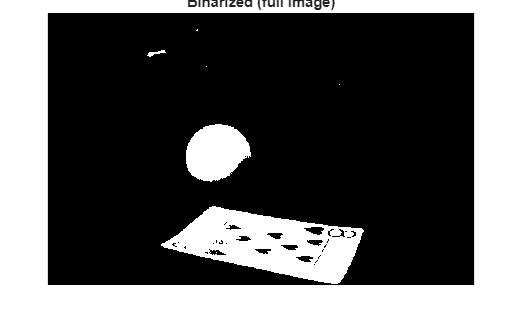


% ---- Binarize (2-D logical) ----
bw = imbinarize(gray);

figure(3);
imshow(bw);
title('Binarized (full image)');

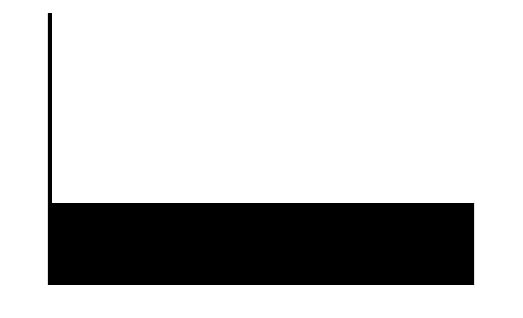


% ---- Keep ONLY top-right region ----
[H, W] = size(bw);

rowCut = round(0.70 * H);   % top 50%
colCut = round(0.01 * W);   % right 30% (tune this)

% mask starts as all FALSE (masked out)
mask = false(H, W);

% set ONLY top-right to TRUE (kept)
mask(1:rowCut, colCut:W) = true;

imshow(mask)

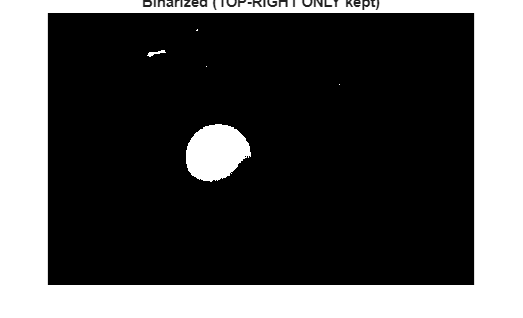


% apply mask: everything outside becomes black (0)
bwTopRightOnly = bw;
bwTopRightOnly(~mask) = 0;

figure(4);
imshow(bwTopRightOnly);
title('Binarized (TOP-RIGHT ONLY kept)');


cc = bwconncomp(bwTopRightOnly);

if cc.NumObjects == 0
    error('No blobs found in ROI.');
end

numPixels = cellfun(@numel, cc.PixelIdxList);
[~, idx] = max(numPixels);

ballMask = false(size(bwTopRightOnly));
ballMask(cc.PixelIdxList{idx}) = true;

stats = regionprops(ballMask, 'Centroid', 'Area');

u = stats.Centroid(1)

u = 297.1860

v = stats.Centroid(2)

v = 246.4490

A = stats.Area

A = 8586

radii = sqrt(A/pi)

radii = 52.2782

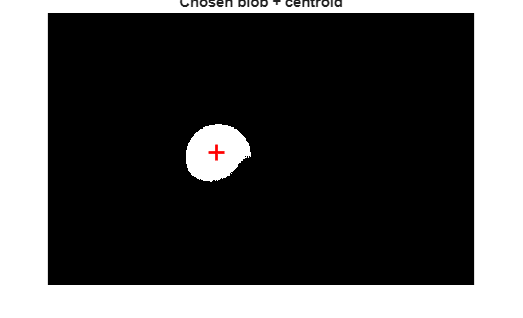


figure;
imshow(ballMask);
title('Chosen blob + centroid');
hold on;
plot(u, v, 'r+', 'MarkerSize', 12, 'LineWidth', 2);
hold off;